clear
load mnist_28.mat

% save mnist_28.mat

%selecting and saving images to train
numE = 160;
validP = 0.25;
idx1 = (training.labels == 1);
place1 = find(cumsum(idx1) > numE-1);
idx2 = (training.labels == 2);
place2 = find(cumsum(idx2) > numE-1);
idx4 = (training.labels == 4);
place4 = find(cumsum(idx4) > numE-1);
idx8 = (training.labels == 8);
place8 = find(cumsum(idx8) > numE-1);
images1 = training.images(:,:,idx1(1:place1));
images2 = training.images(:,:,idx2(1:place2));
images4 = training.images(:,:,idx4(1:place4));
images8 = training.images(:,:,idx8(1:place8));
trainingImages = cat(3, images1(:,:,1:(numE*(1-validP))), images2(:,:,1:numE*(1-validP)), images4(:,:,1:numE*(1-validP)), images8(:,:,1:numE*(1-validP)));
validationImages = cat(3, images1(:,:,(numE*(1-validP)+1):numE), images2(:,:,(numE*(1-validP)+1):numE), images4(:,:,(numE*(1-validP)+1):numE), images8(:,:,(numE*(1-validP)+1):numE));

trainingImagesNoised = trainingImages - randn(28)/10;
delete('trainingImages2\*')
for k = 1:size(trainingImagesNoised, 3)
    imwrite(trainingImagesNoised(:,:,k),"trainingImages2\image"+num2str(k)+".png");
end

validationImagesNoised = validationImages - randn(28)/10;
delete('validationImages2\*')
for k = 1:size(validationImagesNoised, 3)
imwrite(validationImagesNoised(:,:,k),"validationImages2\image"+num2str(k)+".png");
end

%creating imagedatastore from the files
imds = imageDatastore("trainingImages2\");
valds = imageDatastore("validationImages2\");

%creating a pixellabeldatastore
ldc = labelDefinitionCreator();
addLabel(ldc,'on',labelType.PixelLabel);
addLabel(ldc,'off',labelType.PixelLabel);
labelDefs = create(ldc);
clear pixelLabelImages
pixelIdx = trainingImages ~= 0;
pixelLabelImages(28,28,1:size(trainingImages, 3)) = 0;
pixelLabelImages(pixelIdx) = 1;
pixelLabelImages(~pixelIdx) = 2;
pixelLabelImages = uint8(pixelLabelImages);
clear dataFile;
dataFile(size(trainingImages, 3),1) = "a";

delete('pixelLabelImages2\*')
for k = 1:size(trainingImages, 3)
    imwrite(pixelLabelImages(:,:,k),"pixelLabelImages2\image"+num2str(k)+".png");
    dataFile(k,1) = pwd+"\pixelLabelImages2\image"+num2str(k)+".png";
end


labelData = table(dataFile,'VariableNames',{'PixelLabelData'});
gtDataSource = groundTruthDataSource(imds);

gTruth = groundTruth(gtDataSource,labelDefs,labelData);
pxds = pixelLabelDatastore(gTruth);
pximds = combine(imds,pxds);

%doing the same thing for validation set
clear pixelLabelValImages
pixelValIdx = validationImages ~= 0;
pixelLabelValImages(28,28,1:size(validationImages, 3)) = 0;
pixelLabelValImages(pixelValIdx) = 1;
pixelLabelValImages(~pixelValIdx) = 2;
pixelLabelValImages = uint8(pixelLabelValImages);
clear dataFileVal;
dataFileVal(size(validationImages, 3),1) = "a";

delete('pixelLabelValImages2\*')
for k = 1:size(validationImages, 3)
    imwrite(pixelLabelValImages(:,:,k),"pixelLabelValImages2\image"+num2str(k)+".png");
    dataFileVal(k,1) = pwd+"\pixelLabelValImages2\image"+num2str(k)+".png";
end

labelDataVal = table(dataFileVal,'VariableNames',{'PixelLabelData'});
gtDataSourceVal = groundTruthDataSource(valds);
gTruthVal = groundTruth(gtDataSourceVal,labelDefs,labelDataVal);
pxdsVal = pixelLabelDatastore(gTruthVal);
pximdsVal = combine(valds,pxdsVal);

%creating encoder decoder structure
encoderBlock = @(growthRate, inputDepth) [
    convolution2dLayer(3,inputDepth,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth+growthRate,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth+growthRate*2,"Padding",'same')
    batchNormalizationLayer
    reluLayer("Name","db"+num2str(inputDepth))];
decoderBlock = @(growthRate, inputDepth) [
    convolution2dLayer(3,inputDepth,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth-growthRate,"Padding",'same')
    batchNormalizationLayer
    reluLayer];

layers = [
    imageInputLayer([28 28 1])
    convolution2dLayer(3, 8, Padding="same")
    reluLayer
    encoderBlock(16,32)
    maxPooling2dLayer(2,"Stride",2)
    encoderBlock(32,64)
    maxPooling2dLayer(2,"Stride",2)
    convolution2dLayer(3, 128, Padding="same")
    reluLayer
    convolution2dLayer(3, 256, Padding="same")
    reluLayer
    transposedConv2dLayer(2,128,"Stride",2, "Name", "up1")
    depthConcatenationLayer(2)
    decoderBlock(64, 128)
    transposedConv2dLayer(2,64,"Stride",2, "Name","up2")
    depthConcatenationLayer(2)
    decoderBlock(32,64)
    convolution2dLayer(3, 16, Padding="same")
    reluLayer
    convolution2dLayer(3, 8, Padding="same")
    reluLayer
    convolution2dLayer(3, 2, Padding="same")
    softmaxLayer
    pixelClassificationLayer
];


%setting training options
options = trainingOptions( ...
'adam',...
'MiniBatchSize', 480,...
'MaxEpochs',200, ...
'Plots', 'training-progress', ...
'ValidationData', pximdsVal, ...
'ValidationFrequency',20, ...
'ValidationPatience',10);

%training net
net =  trainNetwork(pximds, lgraph_1, options)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |       81.52% |       80.69% |       0.6158 |       0.4019 |          0.0010 |
|      20 |          20 |       00:00:38 |       85.72% |       84.62% |       0.2803 |       0.3052 |          0.0010 |
|      40 |          40 |       00:01:06 |       86.61% |       84.42% |       0.2682 |       0.3138 |          0.0010 |
|      50 |          50 |       00:01:22 |       87.08% |              |       0.2576 |              |          0.0010 |
|      6

net =   DAGNetwork with properties:

         Layers: [51×1 nnet.cnn.layer.Layer]
    Connections: [52×2 table]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


save mnist_28.mat

% %test code
% for k=1:12
%     idx = 1;
%     trueCheck = 0;
%     while trueCheck ~= 1
%     idx = randi(size(test.images,3));
%     if test.labels(idx) == (4)
%         trueCheck = 1;
%     end  
%     end
%     subplot(2,12,k)
%     imshow(test.images(:,:,idx)*255)
%     title("ground "+num2str(idx))
%     subplot(2,12,k+12)
%     prediction = predict(net,test.images(:,:,idx)*255);
%     imshow(prediction(:,:,1))
%     title("prediction "+num2str(idx))
% end

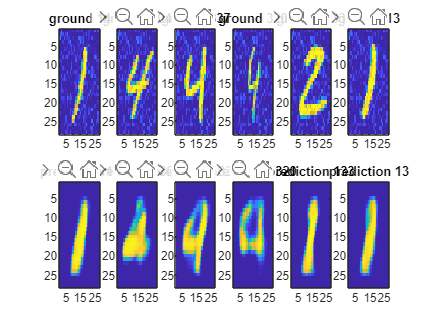

for k=1:6
    idx = randi(size(trainingImagesNoised,3));
    subplot(2,6,k)
    image(trainingImagesNoised(:,:,idx)*255)
    title("ground "+num2str(idx))
    subplot(2,6,k+6)
    prediction = predict(net,trainingImagesNoised(:,:,idx)*255);
    image(prediction(:,:,1)*255)
    title("prediction "+num2str(idx))
end